# Stiffness and Thermal Expansion Predictions for Unidirectional Orientation

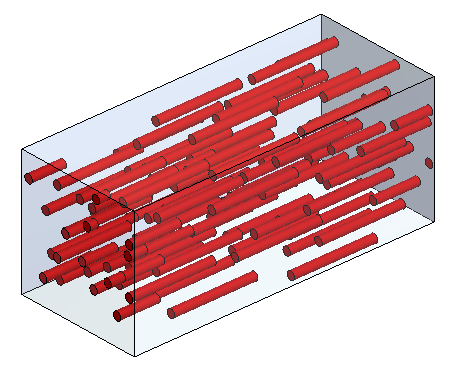

Section 8.2 discusses several mean-field models for predicting the stiffness of a discontinuous fiber composite with unidirectional orientation, and Section 8.6.2 shows how the thermal expansion tensor can be calculated once the stiffness is known.  Here we use the functions `mori`, `lielens` and `halpin` to calculate these properties for the Mori-Tanaka, Lielens/double inclusion, and Halpin-Tsai models, respectively.  Several other functions from the toolkit are also used here.

We'll choose the properties of E-glass fibers and a polycarbonate matrix from Table 8.2, with a fiber volume fraction of $\phi_f$ = 0.20 and a fiber aspect ratio $\ell/d_f$ = 10, and compare the predictions of the three models.

% Input data for all models:
Ef     = 73;     % Fiber modulus, GPa
nuf    =  0.21;  % Fiber Poisson ratio
alphaf =  4.9;   % Fiber thermal expansion, 1e-6/K
Em     =  2.24;  % Matrix modulus, GPa
num    =  0.38;  % Matrix Poisson ratio
alpham = 65;     % Matrix thermal expansion, 1e-6/K
vf     =  0.20;  % Fiber volume fraction
aspect = 10;     % Fiber aspect ratio, l/d

% Stiffness tensors for fiber and matrix
Cf = iso2C(Ef, nuf);
Cm = iso2C(Em, num);

R4 = diag([1,1,1,2,2,2]); % Used for tensor products

% Mori-Tanaka model
% - Stifness tensor and thermal stress tensor
[Cmori, betaMori] = mori(Cf, Cm, vf, aspect, alphaf, alpham);
% - Engineering constants for stiffness
EngMori = C2eng(Cmori);
% - Thermal expansion tensor
alphaMori = inv4(Cmori) * R4 * betaMori; 


% Lielens/double inclusion model
% - Stifness tensor and thermal stress tensor
[Clielens, betaLielens] = ...
       lielens(Cf, Cm, vf, aspect, alphaf, alpham);
% - Engineering constants for stiffness
EngLielens = C2eng(Clielens); 
% - Thermal expansion tensor
alphaLielens = inv4(Clielens) * R4 * betaLielens; 

% Halpin-Tsai model
% - Engineering constants, stiffness and thermal stress
[EngHalpin, Chalpin, betaHalpin] = ...
     halpin(Ef, nuf, Em, num, vf, aspect, alphaf, alpham);
% - Thermal expansion tensor
alphaHalpin = inv4(Chalpin) * R4 * betaHalpin; 

Note that we used `iso2C` to get the stiffness tensors for the fiber and matrix, which are isotropic.  Both `mori` and `lielens` return the stiffness tensor $\mathbb{C}$, and `C2eng` is then used to get the engineering constants.  Type `help C2eng` to see how the engineering constants are arranged in a column vector by this function.  

Rather than calculating thermal expansion, all three functions return $\mathbf{\beta}$, the thermal stress tensor.  This is because $\mathbf{\beta}$ is needed when averaging over multiple orientations.  The thermal expansion tensor $\mathbf{\alpha}$ is then found from Eqn. (8.94), $\mathbf{\alpha} = \mathbb{C}^{-1} : \mathbf{\beta}$.  In Matlab this is `alpha = inv4(C) * R4 * beta`.  

Here is a table of the results calculated above:

fprintf('Model        E11   E22   G12    G23   nu12\n')

Model        E11   E22   G12    G23   nu12


fprintf('Mori-Tanaka %5.2f %5.2f %5.2f  %5.2f  %5.3f\n', ...
        EngMori([1, 2, 6, 4, 9]))

Mori-Tanaka 16.03  3.50  1.19   1.13  0.341


fprintf('Lielens     %5.2f %5.2f %5.2f  %5.2f  %5.3f\n', ...
        EngLielens([1, 2, 6, 4, 9]))  

Lielens     16.08  3.61  1.24   1.17  0.338


fprintf('Halpin-Tsai %5.2f %5.2f %5.2f  %5.2f  %5.3f\n', ...
        EngHalpin([1, 2, 6, 4, 9]))

Halpin-Tsai 14.81  3.74  1.19   1.13  0.346


fprintf('Elastic moduli units are GPa\n')

Elastic moduli units are GPa



fprintf('Model         alpha_11   alpha_22\n')

Model         alpha_11   alpha_22


fprintf('Mori-Tanaka     %5.2f     %5.1f\n', alphaMori(1:2))

Mori-Tanaka     12.08      66.0


fprintf('Lielens         %5.2f     %5.1f\n', alphaLielens(1:2))

Lielens         12.28      64.4


fprintf('Halpin-Tsai     %5.2f     %5.1f\n', alphaHalpin(1:2))

Halpin-Tsai     12.69      42.4


fprintf('Thermal expansion coefficients units are 1e-6/K\n')

Thermal expansion coefficients units are 1e-6/K


The stiffness predictions are similar for all three models.  The Lielens model is stiffer than the Mori-Tanaka model, as it must be at any volume fraction other than 0 or 1, though the difference is very small in this case.  The Halpin-Tsai equation is less stiff than Mori-Tanaka in the fiber direction ($E_{11}$) but stiffer transverse to the fibers ($E_{22}$).

The thermal expansion coefficients in the fiber direction are greatly reduced from the matrix value of 65, and all three models give similar values of $\alpha_{11}$.  The transverse expansion $\alpha_{22}$ is still slightly above the matrix value for the Mori-Tanaka model, and just below it for the Lielens model.  If you reduce the fiber volume fraction `vf` and re-run the script, you will see $\alpha_{22}$ values greater than the matrix value.  This occurs because the fibers constrain the matrix expansion in the fiber direction, while the matrix is trying to expand in all directions.  

Curiously, Halpin-Tsai gives a noticeably smaller transverse expansion coefficient than the other two models.  This may be because the Halpin-Tsai stiffness model imposes less constraint of the matrix in the fiber direction (it has lower $E_{11}$) but greater constraint in the transverse direction (it has higher $E_{22}$).  

The Mori-Tanaka and Lielens models are recommended for most purposes.  